clc;
clear;
syms ui uo u_c1 u_c2 u_R1 u_L2 i i1 i2 s C1 C2 L2 R1
eqs=[
    ui-u_c1-u_R1==0;
    u_c1-u_c2-u_L2==0;
    u_c2-uo==0;

    -i+i1+i2==0;

    u_c1==i1/(C1*s);
    u_c2==i2/(C2*s);
    u_R1==i*R1;
    u_L2==i2*L2*s;
]

$$eqs = \left(\begin{array}{c} \mathrm{ui}-u_{\mathrm{c1}}-u_{\mathrm{R1}}=0\\ u_{\mathrm{c1}}-u_{\mathrm{L2}}-u_{\mathrm{c2}}=0\\ u_{\mathrm{c2}}-\mathrm{uo}=0\\ i_{1}-i+i_{2}=0\\ u_{\mathrm{c1}}=\frac{i_{1}}{C_{1}\,s}\\ u_{\mathrm{c2}}=\frac{i_{2}}{C_{2}\,s}\\ u_{\mathrm{R1}}=R_{1}\,i\\ u_{\mathrm{L2}}=L_{2}\,i_{2}\,s \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,u_c1)

$$eqs = \left(\begin{array}{c} u_{\mathrm{L2}}+u_{\mathrm{R1}}+u_{\mathrm{c2}}=\mathrm{ui}\\ u_{\mathrm{c2}}=\mathrm{uo}\\ i=i_{1}+i_{2}\\ \mathrm{ui}-u_{\mathrm{R1}}=\frac{i_{1}}{C_{1}\,s}\\ i_{2}=C_{2}\,s\,u_{\mathrm{c2}}\wedge C_{2}\neq 0\wedge s\neq 0\\ u_{\mathrm{R1}}=R_{1}\,i\\ u_{\mathrm{L2}}=L_{2}\,i_{2}\,s \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,u_c2)

$$eqs = \left(\begin{array}{c} u_{\mathrm{L2}}+u_{\mathrm{R1}}+\mathrm{uo}=\mathrm{ui}\\ i=i_{1}+i_{2}\\ \mathrm{ui}-u_{\mathrm{R1}}=\frac{i_{1}}{C_{1}\,s}\\ C_{2}\neq 0\wedge s\neq 0\wedge i_{2}=-C_{2}\,s\,\left(u_{\mathrm{L2}}+u_{\mathrm{R1}}-\mathrm{ui}\right)\\ u_{\mathrm{R1}}=R_{1}\,i\\ u_{\mathrm{L2}}=L_{2}\,i_{2}\,s \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,u_R1)

$$eqs = \left(\begin{array}{c} i=i_{1}+i_{2}\\ i_{1}=C_{1}\,s\,\left(u_{\mathrm{L2}}+\mathrm{uo}\right)\wedge C_{1}\neq 0\wedge s\neq 0\\ i_{2}=C_{2}\,s\,\mathrm{uo}\wedge C_{2}\neq 0\wedge s\neq 0\\ \mathrm{ui}-u_{\mathrm{L2}}-\mathrm{uo}=R_{1}\,i\\ u_{\mathrm{L2}}=L_{2}\,i_{2}\,s \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,i)

$$eqs = \left(\begin{array}{c} i_{1}=C_{1}\,s\,\left(u_{\mathrm{L2}}+\mathrm{uo}\right)\wedge C_{1}\neq 0\wedge s\neq 0\\ i_{2}=C_{2}\,s\,\mathrm{uo}\wedge C_{2}\neq 0\wedge s\neq 0\\ \mathrm{ui}-u_{\mathrm{L2}}-\mathrm{uo}=R_{1}\,\left(i_{1}+i_{2}\right)\\ u_{\mathrm{L2}}=L_{2}\,i_{2}\,s \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,u_L2)

$$eqs = \left(\begin{array}{c} i_{2}=C_{2}\,s\,\mathrm{uo}\wedge C_{2}\neq 0\wedge s\neq 0\\ i_{1}+C_{1}\,R_{1}\,s\,\left(i_{1}+i_{2}\right)=C_{1}\,s\,\mathrm{ui}\wedge C_{1}\neq 0\wedge s\neq 0\\ i_{1}=C_{1}\,s\,\left(\mathrm{uo}+L_{2}\,i_{2}\,s\right)\wedge C_{1}\neq 0\wedge s\neq 0 \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,i2)

$$eqs = \left(\begin{array}{c} i_{1}+C_{1}\,R_{1}\,s\,\left(i_{1}+C_{2}\,s\,\mathrm{uo}\right)=C_{1}\,s\,\mathrm{ui}\wedge C_{1}\neq 0\wedge s\neq 0\\ i_{1}=C_{1}\,s\,\mathrm{uo}\,\left(C_{2}\,L_{2}\,s^{2}+1\right)\wedge C_{1}\neq 0\wedge s\neq 0 \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,i1)

$$eqs = C_{1}\neq 0\wedge s\neq 0\wedge \frac{C_{1}\,s\,\mathrm{ui}-C_{1}\,C_{2}\,R_{1}\,s^{2}\,\mathrm{uo}}{C_{1}\,R_{1}\,s+1}=C_{1}\,s\,\mathrm{uo}\,\left(C_{2}\,L_{2}\,s^{2}+1\right)$$

uo=solve(eqs,uo)

$$uo = \frac{\mathrm{ui}}{C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,L_{2}\,s^{2}+C_{1}\,C_{2}\,L_{2}\,R_{1}\,s^{3}+1}$$

gs=uo/ui

$$gs = \frac{1}{C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,L_{2}\,s^{2}+C_{1}\,C_{2}\,L_{2}\,R_{1}\,s^{3}+1}$$

gs=subs(gs,[R1,L2,C1,C2],[1,1,1,1])

$$gs = \frac{1}{s^{3}+s^{2}+2\,s+1}$$

hs=gs/s

$$hs = \frac{1}{s\,\left(s^{3}+s^{2}+2\,s+1\right)}$$

ht=ilaplace(hs)

$$ht = \begin{array}{l} 1-\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\sigma_{1}\,t}\,\sigma_{1}}{2\,\sigma_{1}+3\,{\sigma_{1}}^{2}+2}\right)-\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{1}}\,{\sigma_{1}}^{2}}{3\,{\sigma_{1}}^{2}+2\,\sigma_{1}+2}\right)-2\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{1}}}{3\,{\sigma_{1}}^{2}+2\,\sigma_{1}+2}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left(z^{3}+z^{2}+2\,z+1,z,k\right) \end{array}$$

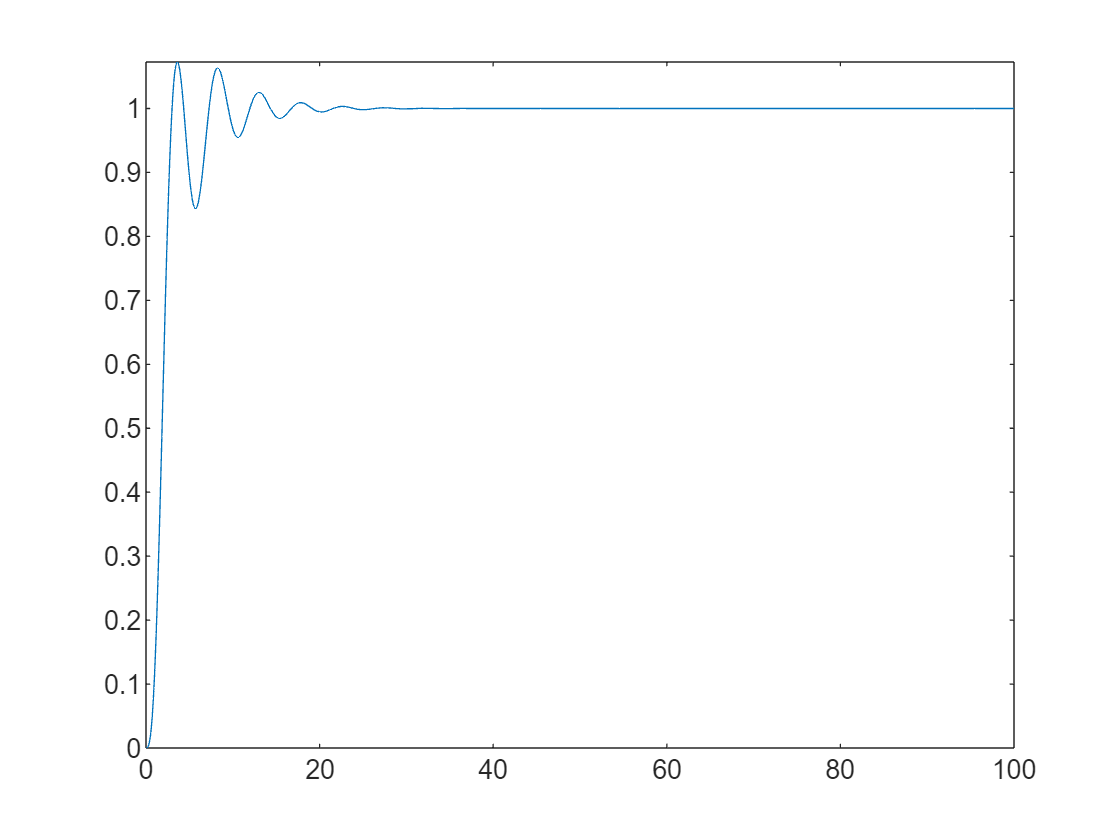

fplot(ht,[0,100])

[num,den]=numden(gs)

$$num = 1$$

$$den = s^{3}+s^{2}+2\,s+1$$

p_den=solve(den,s)

$$p\_den = \left(\begin{array}{c} \mathrm{root}\left(z^{3}+z^{2}+2\,z+1,z,1\right)\\ \mathrm{root}\left(z^{3}+z^{2}+2\,z+1,z,2\right)\\ \mathrm{root}\left(z^{3}+z^{2}+2\,z+1,z,3\right) \end{array}\right)$$

p_den=double(p_den)

p_den =   -0.5698 + 0.0000i
  -0.2151 - 1.3071i
  -0.2151 + 1.3071i


gs=sym2tf(gs)

gs =
 
           1
  -------------------
  s^3 + s^2 + 2 s + 1
 
连续时间传递函数。
模型属性


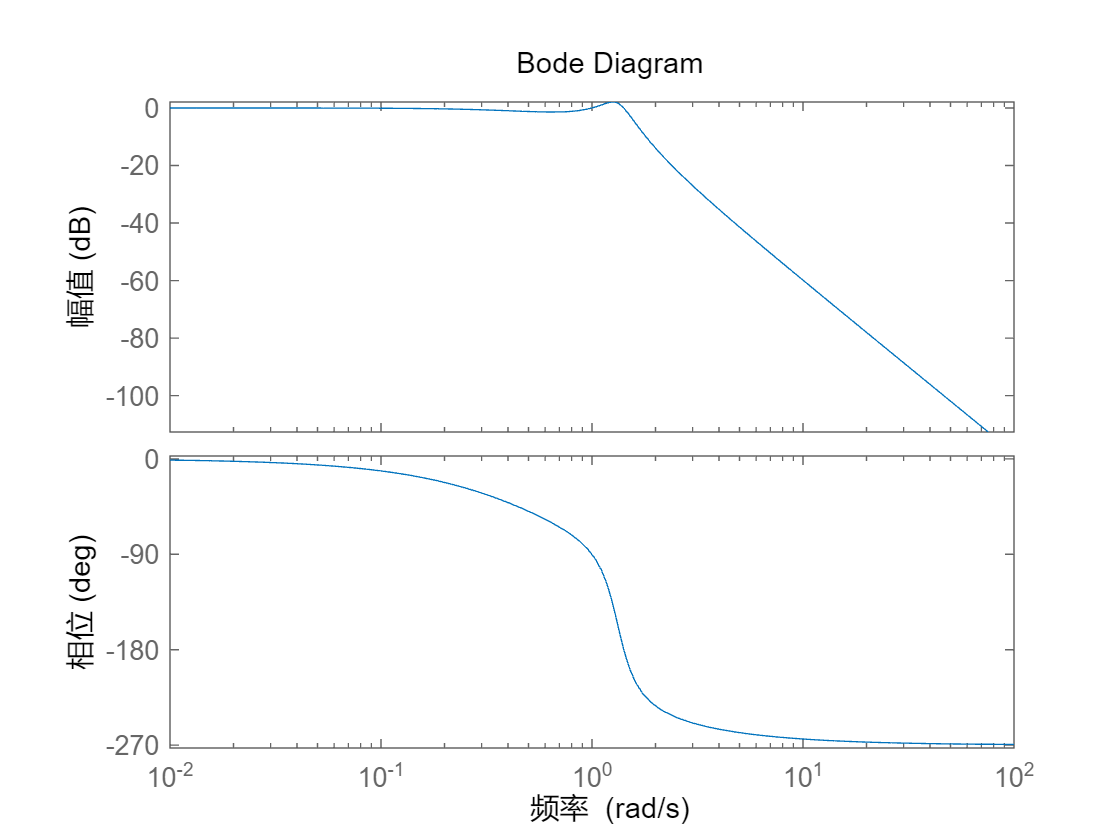

bode(gs)